clear;clc;close all
syms x Omega kappa Delta g n epsilon real
assume(Omega>0)
assume(kappa>0)
assume(Delta>0)
assume(g>0)
assume(n>0)
V=1/2*Omega*x.^2+...
    n*(Delta^2+kappa^2/4)/(kappa/2).*...
    (   atan( (Delta+g*x)/(kappa/2)   )   ...
    +   atan( (Delta-g*x)/(kappa/2)   )    )  %(1-10^-11)

$$V = \frac{\Omega \,x^{2}}{2}+\frac{2\,n\,\left(\Delta^{2}+\frac{\kappa^{2}}{4}\right)\,\left(\mathrm{atan}\left(\frac{2\,\left(\Delta +g\,x\right)}{\kappa }\right)+\mathrm{atan}\left(\frac{2\,\left(\Delta -g\,x\right)}{\kappa }\right)\right)}{\kappa }$$


dV=diff(V,x);
%ddV=diff(dV,x);
dV_0=solve(dV,x)

$$dV\_0 = \begin{array}{l} \left(\begin{array}{c} 0\\ \sigma_{1}\\ \sigma_{2}\\ -\sigma_{1}\\ -\sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{-\frac{4\,\sqrt{\Delta }\,\sqrt{4\,n\,\Delta^{2}\,g^{2}-\Omega \,\Delta \,\kappa^{2}+n\,g^{2}\,\kappa^{2}}-4\,\Delta^{2}\,\sqrt{\Omega }+\sqrt{\Omega }\,\kappa^{2}}{4\,\sqrt{\Omega }\,g^{2}}}\\ \sigma_{2}=\sqrt{\frac{4\,\sqrt{\Delta }\,\sqrt{4\,n\,\Delta^{2}\,g^{2}-\Omega \,\Delta \,\kappa^{2}+n\,g^{2}\,\kappa^{2}}+4\,\Delta^{2}\,\sqrt{\Omega }-\sqrt{\Omega }\,\kappa^{2}}{4\,\sqrt{\Omega }\,g^{2}}} \end{array}$$

n0=solve(dV_0(3)==0,n)

$$n0 = \frac{4\,\Omega \,\Delta^{2}+\Omega \,\kappa^{2}}{16\,\Delta \,g^{2}}$$


L = 1*10^1; % Region size
hbar = 1; % Reduced Planck's constant
m = 1;    % Electron mass
% Define the size of the region and the number of points for discretization
N = 5*10^5;   % Number of points for discretization
N_state=4;   % Number of states from vacuum
dx = L / N; % Discretization step
x = linspace(-L/2, L/2, N);
%% % Define the potential function
% Vpar.Omega=2*pi; %Hz
% Vpar.kappa=2*pi*10^6; %Hz
% Vpar.Delta=2*pi*10^4; %Hz
% Vpar.g=2*pi*18.75;

Vpar.Omega=2*pi*145*10^3; %Hz
Vpar.kappa=2*pi*580*10^3; %Hz
Vpar.Delta=2*pi*10^4; %Hz
Vpar.g=2*pi*500; %Hz


Vpar.n0=double(subs(n0,[kappa,Omega,g,Delta],[Vpar.kappa,Vpar.Omega,Vpar.g,Vpar.Delta]))

Vpar = struct with fields:
    Omega: 9.1106e+05
    kappa: 3.6442e+06
    Delta: 6.2832e+04
        g: 3.1416e+03
       n0: 1220900


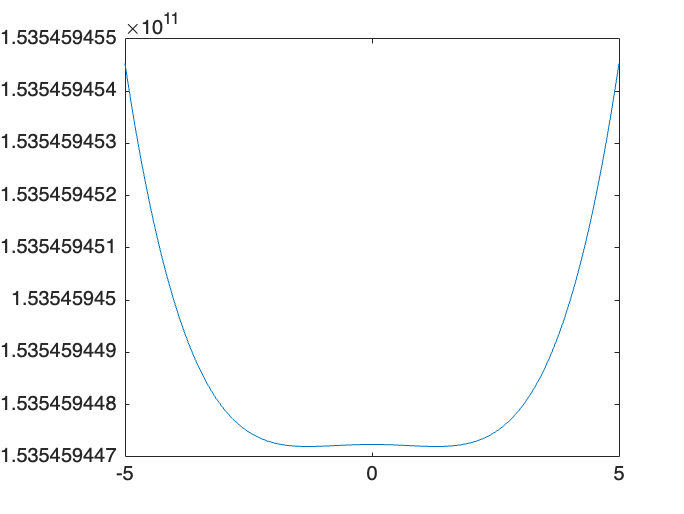

%alpha_V=0.9935695;%%17900*0.9935715 splitiing happens for alpha_V=1
dalpha=10^-5;
alpha_0=1+dalpha;
alpha_V=alpha_0;
Vpar.n=Vpar.n0*alpha_V;
V=1/2*Vpar.Omega*x.^2+...
        Vpar.n*(Vpar.Delta^2+Vpar.kappa^2/4)/(Vpar.kappa/2).*...
        (   atan( (Vpar.Delta+Vpar.g*x)/(Vpar.kappa/2)   )   ...
        +   atan( (Vpar.Delta-Vpar.g*x)/(Vpar.kappa/2)   )    );  %(1-10^-11)
plot(x,V)

%xlim(100*[-1,1])